% Clear old vars
clear
% Connect to raspi
%rpi = raspi()

% Note: use webcam function instead if using a USB camera
cam = Camera()

cam.show()

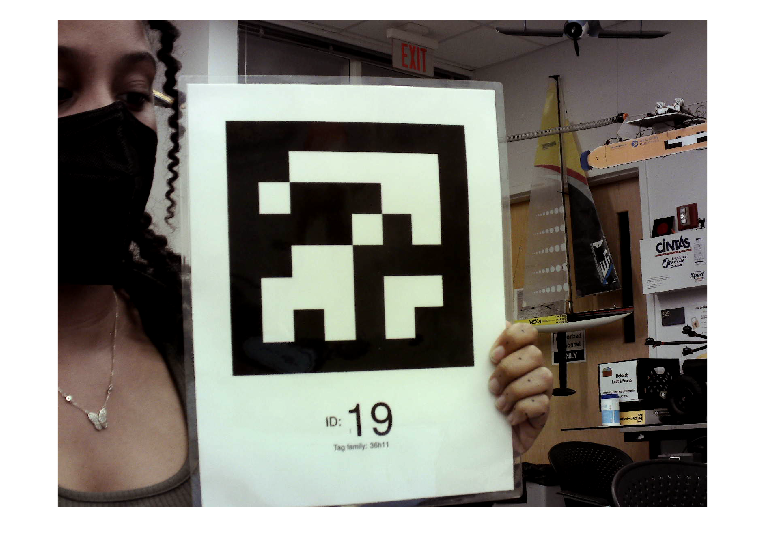

% Flush camera buffer
for v = 0:1:5
    % Take a photo using the camera
   I = snapshot(cam.cam);
end

% Display image
figure, imshow(I)

ids = 19

loc = 	1.0e+03 *

    0.4308    0.8786
    1.0269    0.8551
    1.0044    0.2587
    0.4143    0.2476


detectedFamily = "tag36h11"

Detected Tag ID, Family: 19, tag36h11
   1.0e+03 *

    0.4308    0.8786
    1.0269    0.8551
    1.0044    0.2587
    0.4143    0.2476



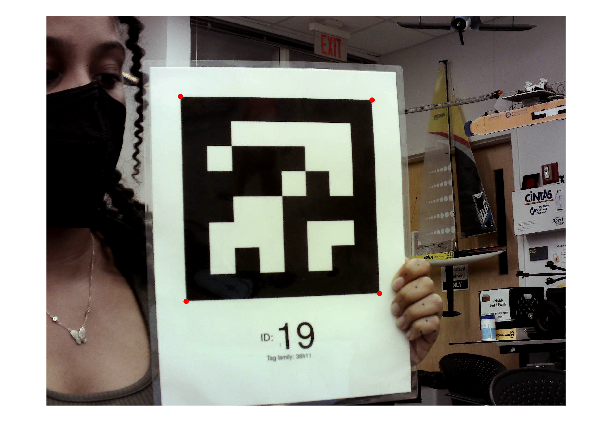

centers =   719.0934  559.9936


ids = 19

loc = 	1.0e+03 *

    0.4308    0.8786
    1.0269    0.8551
    1.0044    0.2587
    0.4143    0.2476


%I = imread("ReadAprilTagsInImageExample_01.png");
[centers, ids, loc] = detectAprilTags(I, true) % Change to false to suppress output

    function [centers, loc, ids] = detectAprilTags(image, display)
    tagFamily = ["tag36h11"];
    
    [ids,loc,detectedFamily] = readAprilTag(image, tagFamily);
    
    centers = zeros(length(ids), 2);
    
    for idx = 1:length(ids)
        % Compute center of tag
        center = mean(loc(:,:,idx));

        % Add 2D center of tag to list
        centers(idx,:) = center;
        
        if display
            % Display the ID and tag family
            disp("Detected Tag ID, Family: " + ids(idx) + ", " ...
                + detectedFamily{idx})
            disp(loc)
            
            % Insert markers to indicate the locations
            markerRadius = 8;
            numCorners = size(loc,1);
            markerPosition = [loc(:,:,idx),repmat(markerRadius,numCorners,1)];
            image = insertShape(image,"FilledCircle",markerPosition,"Color","red","Opacity",1);
        end
    end
    
    if display
        imshow(image);
    end
end